# GEM Analysis

## Set up filepaths

% Find the ssADGEM project dir location
script_path = fileparts(matlab.desktop.editor.getActiveFilename);
project_path = extractBefore(script_path, "code");

% Load up the Human-GEM
% Load variables
ref_gem_path = strjoin([project_path, "external/human_dir/model/Human-GEM.mat"], "");
Human_GEM = load(ref_gem_path);
ihuman = Human_GEM.ihuman;
clear Human_GEM;

% Find the GEM files
GEMs_dir = strjoin([project_path, "data/ROSMAP_GEMs/"], "");
model_files = dir(fullfile(GEMs_dir,'*.mat'));
model_paths = arrayfun(@(x) strjoin([GEMs_dir, x.name], ""), model_files);

% Load metadata and convert sample names with hash key
metadata_path = strjoin([project_path, "data/ROSMAP_metadata.txt"], "");
ROSMAP_metadata = readtable(metadata_path);

key_path = strjoin([project_path, "data/HASH_key.csv"], "");
HASH_key = readtable(key_path, Delimiter=",");
if all(ismember(HASH_key.Samples,ROSMAP_metadata.SampleID))
    ROSMAP_metadata.SampleID = HASH_key.Hash;
end

% Sort to match model, also exclude models not present
model_names = extractBetween({model_files.name}', "ROSMAP_", ".mat");
ROSMAP_metadata = sortrows(ROSMAP_metadata, 'SampleID');
ROSMAP_metadata = ROSMAP_metadata(...
    ismember(ROSMAP_metadata.SampleID, model_names),...
    :);

## Construct logical of reactions present in each model

% Preallocate the logical (rows are reactions, columns are models)
rxns_logical = false(length(ihuman.rxns), length(model_paths));

% Load the models
for i = 1:length(model_paths)

    rxns_logical(:, i) = ismember(ihuman.rxns, ...
        load(model_paths(i)).model.rxns);

end

## Project with t-sne

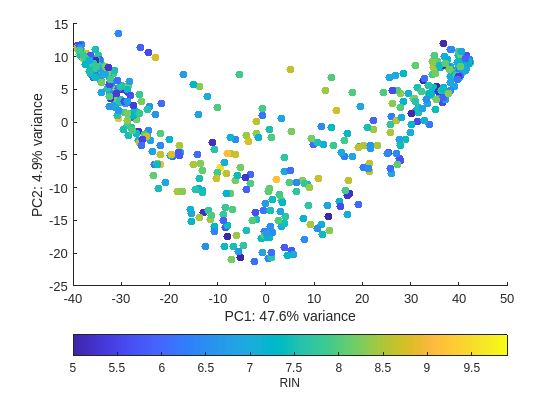

% MATLAB defaults to rows as observation, hence the transpose
[coeff,score,latent,tsquared,explained] = pca(double(rxns_logical'));

% Visualize
possible_grouping_variables = string(ROSMAP_metadata.Properties.VariableNames);
grouping_var = possible_grouping_variables(2);
if length(unique(ROSMAP_metadata.(grouping_var))) > 10

    % Assume continuous variable
    p = scatter(score(:,1),score(:,2), [], ROSMAP_metadata.(grouping_var), 'filled');
    c = colorbar('southoutside');
    c.Label.String = grouping_var;
else

    % Assume categorical variable
    p = gscatter(score(:,1),score(:,2), ROSMAP_metadata.(grouping_var));
end
xlabel(['PC1: ' num2str(explained(1), '%.1f') '% variance'])
ylabel(['PC2: ' num2str(explained(2), '%.1f') '% variance'])
save_path = strjoin([project_path, "nobackup/plots/GEM_pca.png"], "");
saveas(p, save_path)